# Lab 8

% Mo Zhou <mzhou32@jhu.edu>

% Load the dataset
images_train = loadMNISTImages('train-images-idx3-ubyte');
images_test = loadMNISTImages('t10k-images-idx3-ubyte');
labels_train = loadMNISTLabels('train-labels-idx1-ubyte');
labels_test = loadMNISTLabels('t10k-labels-idx1-ubyte');
% put points in rows
images_train = single(images_train');
images_test = single(images_test');

% (a) center the input data, class wise
ncls = 10;
dim = 784;
centers = zeros(ncls, dim);
for i = 1:ncls
    if i == 10
        mask = find(labels_train == 0);
    else
        mask = find(labels_train == i);
    end
    samples = images_train(mask, :);
    %size(samples)
    centers(i, :) = mean(samples, 1);
end

cursor = 1;
cursormask = find(labels_train == cursor);
samples = images_train(cursormask, :);
N = length(cursormask);
D = 784;
K = 50; % (c)
% (b) random init
W = rand(D, K);
sigma = rand();

% (g) loop
for i = 1:3
    % (d) log likelihood
    M = W' * W + sigma^2 * eye(K);
    U = chol(M);
    V = inv(U);
    M_1 = V * V';
    S = sum(vecnorm(samples, 2, 2));
    loglike = -N /2 * (...
        D * log(2 * pi) + log(det(M)) + trace(S * M_1));
    % (e) E step
    fprintf("E(%d)\n", i);
    Ezn = zeros(N, K);
    Eznznt = zeros(N, K, K);
    for j = 1:N
        xn = samples(j, :);
        zn = M_1 * W' * xn';
        Ezn(j, :) = zn;
        znznt = sigma^2 .* M_1 + zn' * zn;
        Eznznt(j, :, :) = znznt;
    end
    % (f) M step
    Wnew = zeros(D, K);
    for j = 1:N
        Wnew = Wnew + samples(j, :)' * Ezn(j, :);
    end
    Wnew = Wnew * inv(reshape(sum(Eznznt, 1), K, K));
    sigma2new = 0;
    for j = 1:N
        tmp = norm(samples(j, :));
        tmp = tmp - 2 * Ezn(j,:) * Wnew' * samples(j, :)';
        tmp = tmp + trace(reshape(Eznznt(j, :, :), K, K) * Wnew' * Wnew);
        sigma2new = sigma2new + tmp;
    end
    sigma2new = sigma2new / (N * D);
    % update
    W = Wnew;
    sigma = sqrt(sigma2new);
end

E(1)


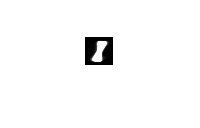

% (i) random latent variable
zgen = randn(K, 1);
% (j) generate image
xgen = W * zgen;
imshow(reshape(xgen, 28, 28));

% (k) batch training
Ws = zeros(ncls, D, K);
sigmas = zeros(1, ncls);
for cls = 1:ncls
    W = rand(D, K);
    sigma = rand();
    if cls == 10
        cursormask = find(labels_train == 0);
    else
        cursormask = find(labels_train == cursor);
    end
    samples = images_train(cursormask, :);
    [W, sigma] = em(samples, W, sigma, 3);
    Ws(cls, :, :) = W;
    sigmas(1, cls) = sigma;
end

% plotting
for cls = 1:ncls
    zgen = randn(K, 25);
    xgen = reshape(Ws(cls, :, :), D, K) * zgen;
    for i = 1:25
        subplot(5,5,i);
        im = reshape(xgen(:, i), 28, 28);
        imshow(im);
    end
end

